# Assignment 2:

#### Lúa Arconada, Nuria Errasti, Alejandro Macías

## 1. Data description

This datasets contains 25 variables and 400 observations. It contains 11 numeric variables and 14 nominal ones (both binary and multinomal) that can be used to predict chronic kidney disease. The dataset was already pre-processed for the previous assignment, and therefore we only have to load the "clean" version of it to be analysed. 

%Load the clean data (cleaned in R in task1)
data_aux=readtable('clean_data.csv');

%Eliminate the first row, identity variable
data_aux = data_aux(:,2:26);

%Set the qualitative variables as categorical
data_aux.rbc=categorical(data_aux.rbc);
data_aux.pc=categorical(data_aux.pc);
data_aux.pcc=categorical(data_aux.pcc);
data_aux.ba=categorical(data_aux.ba);
data_aux.htn=categorical(data_aux.htn);
data_aux.dm=categorical(data_aux.dm);
data_aux.cad=categorical(data_aux.cad);
data_aux.appet=categorical(data_aux.appet);
data_aux.pe=categorical(data_aux.pe);
data_aux.ane=categorical(data_aux.ane);
data_aux.class=categorical(data_aux.class);
data_aux.bp=categorical(data_aux.bp);
data_aux.sg=categorical(data_aux.sg);
data_aux.al=categorical(data_aux.al);
data_aux.su=categorical(data_aux.su);

%We create different tables containing the continuous, binary and
%categorical variables respectively
X1=table2array(data_aux(:,vartype('numeric')));
X2=table2array(data_aux(:,11:21));
X3=table2array(data_aux(:,22:25));
X=[X1,double(X2),double(X3)];

Now, we are going to create a matrix for the binary data that instead of the categories being 'normal' and 'abnormal' (for example), they are all going to be 0's and 1's.

%Take care of the binary data
% Map categories to binary representation
binaryData = zeros(size(X2));
% Map "normal" to 0, "abnormal" to 1 for variables 1 and 2
binaryData(:, [1, 2]) = double(X2(:, [1, 2]) == "abnormal");
% Map "notpresent" to 0, "present" to 1 for variables 3 and 4
binaryData(:, [3, 4]) = double(X2(:, [3, 4]) == "present");
% Map "yes" to 0, "no" to 1 for variables 5, 6, 7, 9, and 10
binaryData(:, [5, 6, 7, 9, 10]) = double(X2(:, [5, 6, 7, 9, 10]) == "no");
% Map "poor" to 0, "good" to 1 for variable 8
binaryData(:, 8) = double(X2(:, 8) == "good");
% Map "notckd" to 0, "ckd" to 1 for variable 11
binaryData(:, 11) = double(X2(:, 11) == "ckd");

## 2. Distances

First of all, before proceding with Multidimensional scaling and Cluster analysis, we will obtain every distance we will use (Gower, Mahalanobis,RelMS,...).  We define first some important values which correspond to the number of continuous, binary and categorical variables, as well as the dimension of our data matrix X.

[n,p]=size(X);
% continuous variables
p1=10;
% binary variables
p2=11;
% categorical variables
p3=p-p1-p2;

### 2.1. Gower's distance (mixed data)

%Similarity matrix
Sgower=gower2(X,p1,p2,p3);

% transform similarity to distance
D2gower=ones(n)-Sgower;
Dgower=sqrt(D2gower);

### 2.2. Mahalanobis' distance (continuous variables)

We can only compute the Mahalanobis distance for continuous variables, so we take X1 instead of X.

Dmaha=pdist(X1, 'mahal');
D2maha=squareform(pdist(X1, 'mahal').^2);

### 2.3. Jaccard & Sokal-Michener's distance (binary variables)

%Jaccard similarity and distance matrices for BINARY variables
[n,p]=size(binaryData);
Sjaccard=jaccard(binaryData);
D2jaccard=2*(ones(n)-Sjaccard);
Djaccard=sqrt(D2jaccard);

%Sokal-Michener similarity and distance matrices for binary variables
Ssokal=sokal(binaryData);
D2sokal=2*(ones(n)-Ssokal);
Dsokal=sqrt(D2sokal);

### 2.4. Similarity coefficients (categorical variables)

We will compute SC1 and SC4.

%Compute similarity coefficients SC1 and SC4 for CATEGORICAL variables
[n,p]=size(X3);
SC1=coincidencias(X3);
D2SC1=2*(ones(n)-SC1);
DSC1=sqrt(D2SC1);

SC4=coincidencias4(X3);
D2SC4=2*(ones(n)-SC4);
DSC4=sqrt(D2SC4);

### 2.5. Hamming's distance (binary and categorical variables)

%We compute the Hamming' distance matrix for categorical AND binary
%variables
Shamming=coincidencias(X(:,p1+1:end));
D2hamming=2*(ones(n)-Shamming);

### 2.6. Joint metrics (Related Metric Scaling)

%Compute joint metric using relms2 and Mahalanobis' distance for
%quantitative variables and Hamming distance for qualitative variables
%We already have the Mahalanobis' distance matrix D_maha

%First term of joint metric (Pythagorean sum)
vg1=sum(sum(D2maha))/(2*n^2);
vg2=sum(sum(D2hamming))/(2*n^2);
D2pyth=D2maha/vg1+D2hamming/vg2;

%Joint metric by RelMS
D2joint=relms2(D2maha,D2hamming);

## 3. Multidimensional scaling (MDS)

The first statistical technique that we will apply is multidimensional scaling. This technique aims to generate a geometric representation of  the distances or similarities between a set of observations. 

The starting point of the MDS algorithm is a squared-distances matrix between each unit in the dataset. Since there are both quantitative and qualitative variables, we will use Gower's distance:

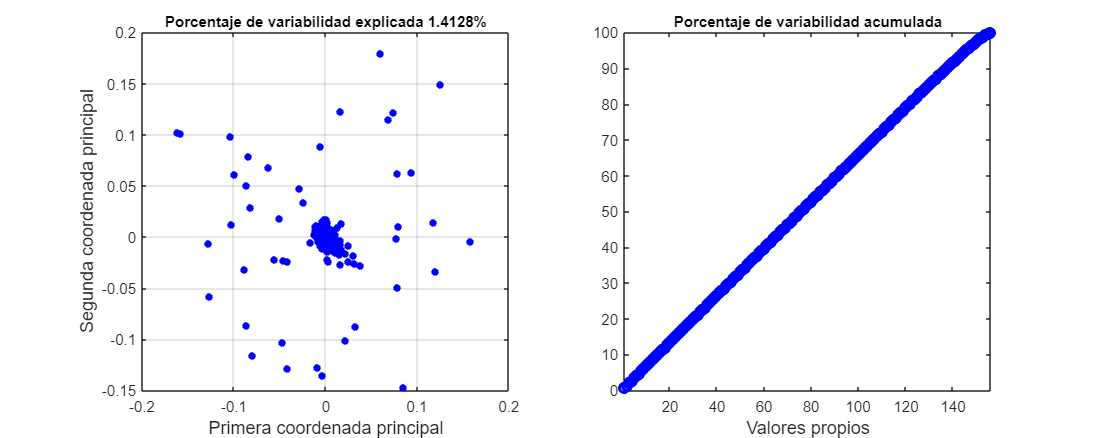

clf('reset')
[Y,vaps,percent,cum]=coorp(D2gower);

Looking at these graphs, we see that more than 100 dimensions are needed to raise the 80% of explained variability. This is not ideal, however we have to use Gower's distance since we have a mixed dataset. 

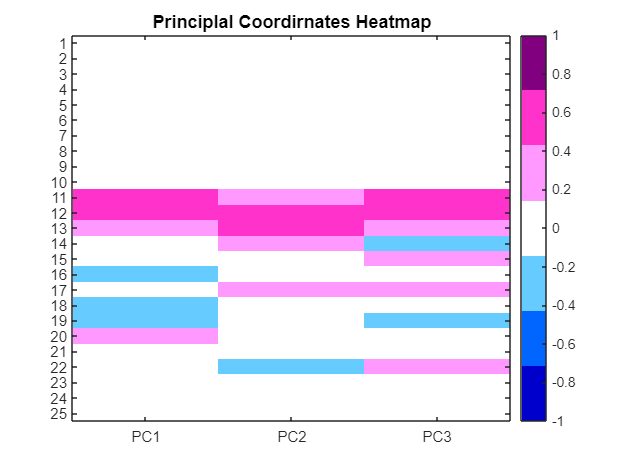

clf('reset')
corr_table=correlaciones2(X,Y(:,1:3),p1,3);

From the heatmap of the cross-correlations/associations between the original variables and the first three prinicipal coordinates we can infer that the most influential variables are the 11th, 12th and 13th, that is, the variables 'rbc' (red blood cells), 'pc' (pus cells) and 'pcc' (pus cell clumps). Variables $X_{11}$ and $X_{12}$ are the most influential on the first and third axis (positive correlation) and $X_{12}$ and $X_{13}$ on the second axis (positive correlation). 

Let us check the partial influence of variables $X_{1}-X_{25}$ in the MDS configurations computed from Gower's distance:

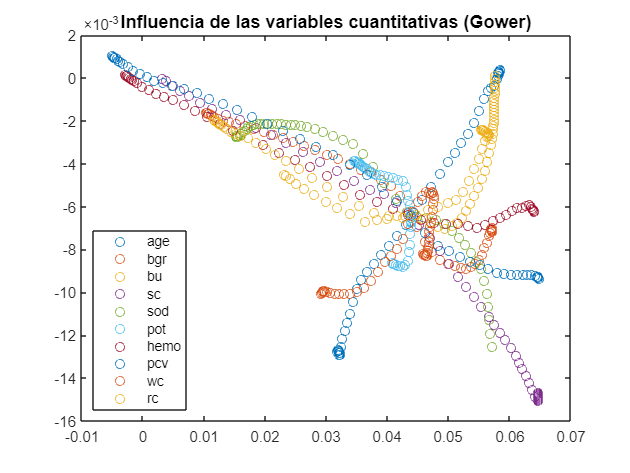

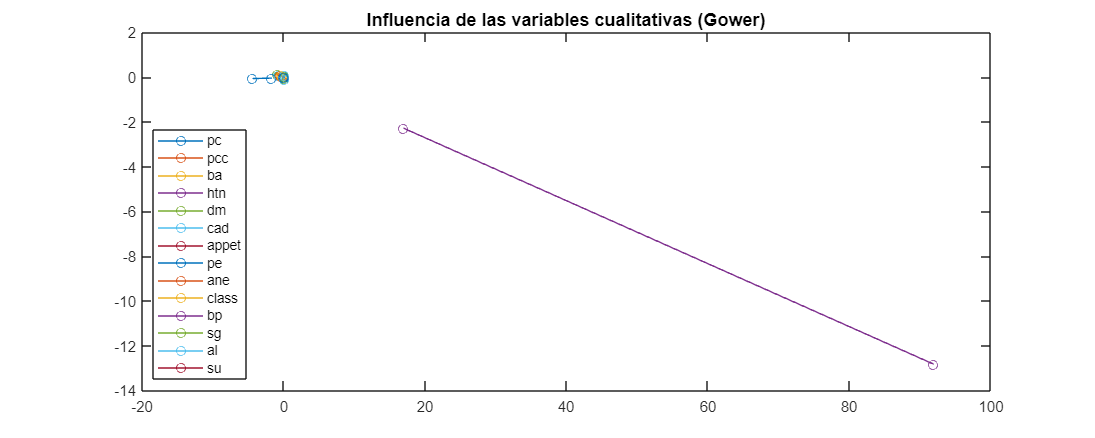

clf('reset'), warning('off');
influence(X,p1,p2);

The most influential qualitative variable on both axis seem to be $X_{22}$, especially on the first axis. Looking at the influence of the quantitative variables we see that $X_{2}$, $X_{4}$, $X_{5}$, $X_{7}$ and $X_{8}$ are the most influential on the first axis and $X_{1}$, $X_{4}$ and $X_{5}$ on the second one. 

We can now plot the conditional MDS-maps of the most influential variables. In this case, are going to compute the scatterplots of principal coordinates conditioned to $X_{11}$, $X_{12}$ and $X_{13}$.

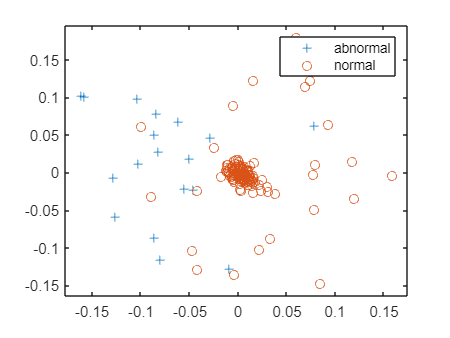

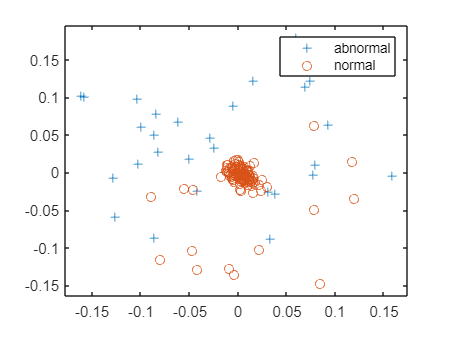

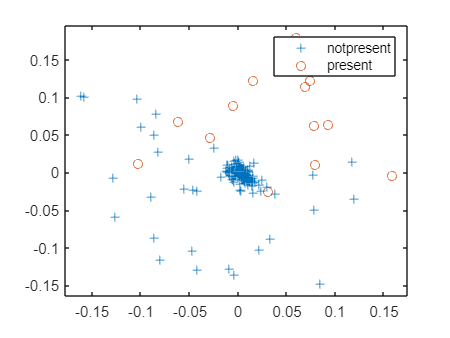

clf('reset')
identif_cualis(X2(:,1:3),Y);

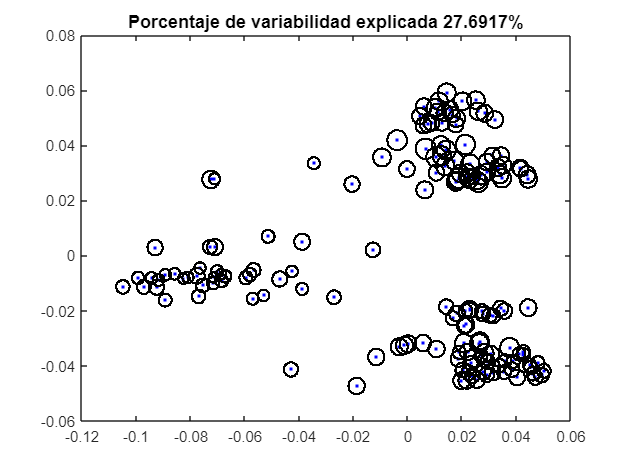

clf('reset')
sensitividad_Gower(X,p1,p2);

We compute once again the Multidimensional Scaling Analysis, but with the Mahalanobis distance (only numerical variables).

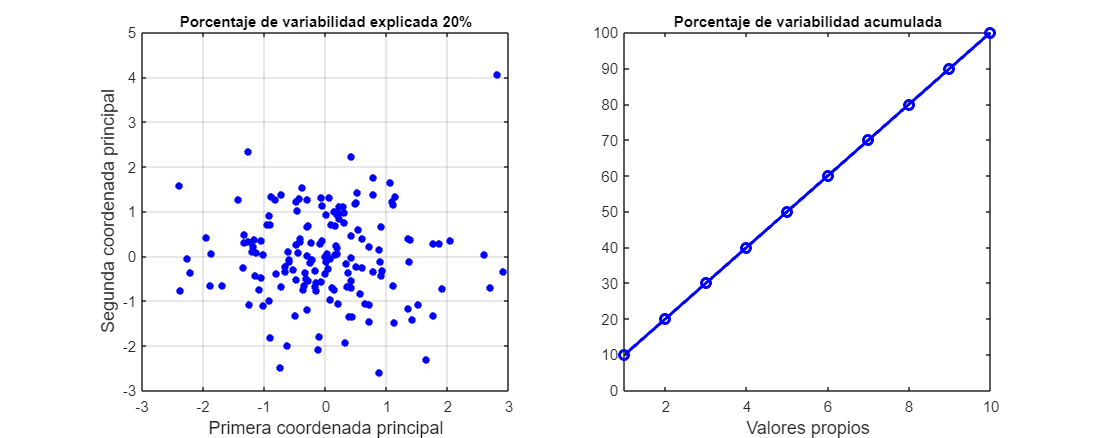

clf('reset')
[Y_m,vaps_m,percent_m,acum_m]=coorp(D2maha);

Now, using Mahalanobis' distance we can see that "only" 8 dimensions are needed to reach  80% of the explained variability. 

We compute the related Metric Scaling once again the Multidimensional Scaling Analysis, but with the Mahalanobis distance (only numerical variables).

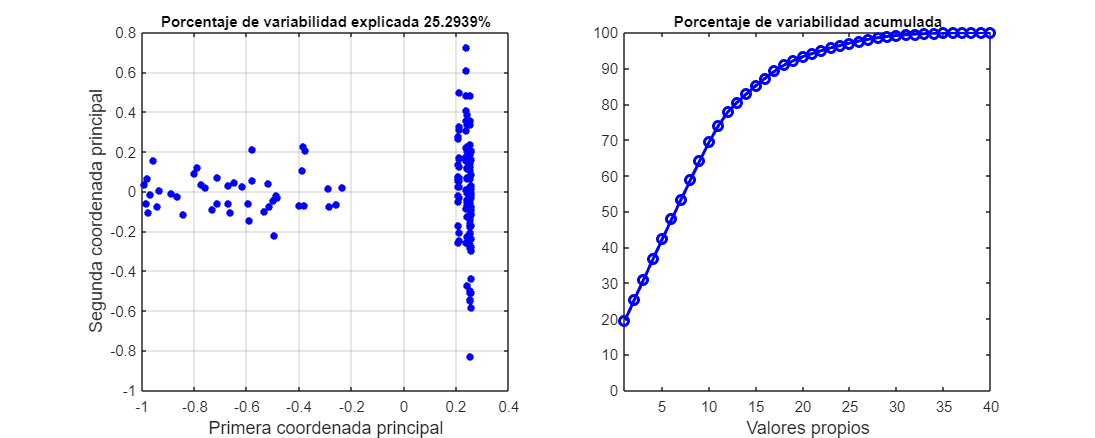

clf('reset')
%RelMS via MDS mapping (Related Metric Scaling);
[Y_joint,vaps_joint,percent_joint,acum_joint]=coorp(D2joint);

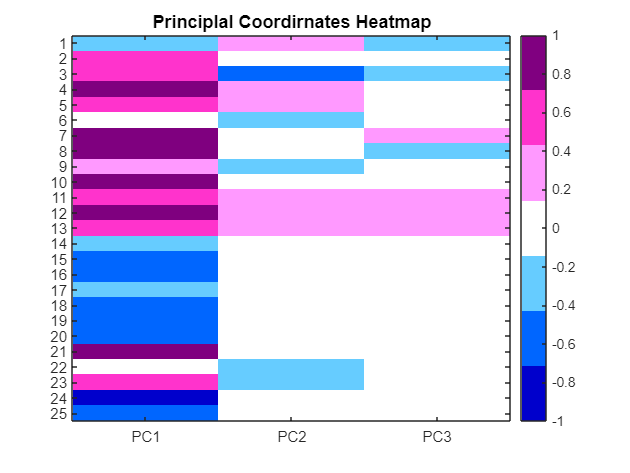

clf('reset')
corr_table_joint=correlaciones2(X,Y_joint(:,1:3),p1,3);

We compare the cross correlations we obtain with Gower's metric and joint metric.

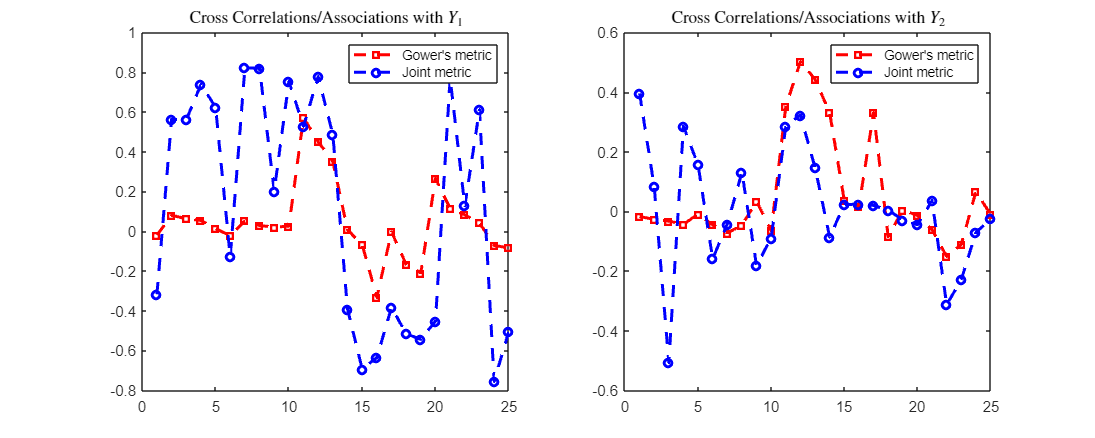

clf('reset')
figure('Position', [100, 100, 1000, 400]);
subplot(1, 2, 1);
plot(corr_table(:,1), 'rs--', 'LineWidth', 2, 'MarkerSize', 5,'DisplayName', 'Gower''s metric');
hold on;
plot(corr_table_joint(:,1), 'bo--', 'LineWidth', 2, 'MarkerSize', 5, 'DisplayName', 'Joint metric');
hold off;
legend('show');
title('Cross Correlations/Associations with $Y_{1}$', 'Interpreter', 'latex');

subplot(1, 2, 2);
plot(corr_table(:,2), 'rs--', 'LineWidth', 2, 'MarkerSize', 5,'DisplayName', 'Gower''s metric');
hold on;
plot(corr_table_joint(:,2), 'bo--', 'LineWidth', 2, 'MarkerSize', 5, 'DisplayName', 'Joint metric');
hold off;
legend('show');
title('Cross Correlations/Associations with $Y_{2}$', 'Interpreter', 'latex');

## 4. Clustering methods

Clustering is a method that consists of finding natural homogeneous groupings or clusters in the observations of our dataset . 

### 4.1. Hierarchical clustering

We will start by using hiersarchical clustering method because our dataset is mixe. We will only need the matrix of dissimilarities and not the original observations. Since it is difficult to decide which is the "best" number of clusters, we will used the rule-of-thumb for selection of number of clusters:$k= \sqrt{\frac{n}{2}} \approx 9$ . 

The cophenetic correlation is different to 1, which means that the original distance matrix D does not fulfill the ultrametric property. Furthermore, this means that the different linkage criteria will yield different clusterings:

% Robustified Gower's distance
Dmaha = robust2_maha(X(:,1:p1));
Djac = 2*(ones(n) - jaccard(X(:,p1+1:p1+p2)));
Dcoin = 2*(ones(n) - coincidencias(X(:,p1+p2+1:end)));
vgmaha = sum(sum(Dmaha))/n^2; vgjac = sum(sum(Djac))/n^2; vgcoin = sum(sum(Dcoin))/n^2;
D = Dmaha/vgmaha + Djac/vgjac + Dcoin/vgcoin;
d = sqrt(squareform(D));
Uave=linkage(d,'average');
Umin = linkage(d, 'single');
Umax = linkage(d, 'complete');

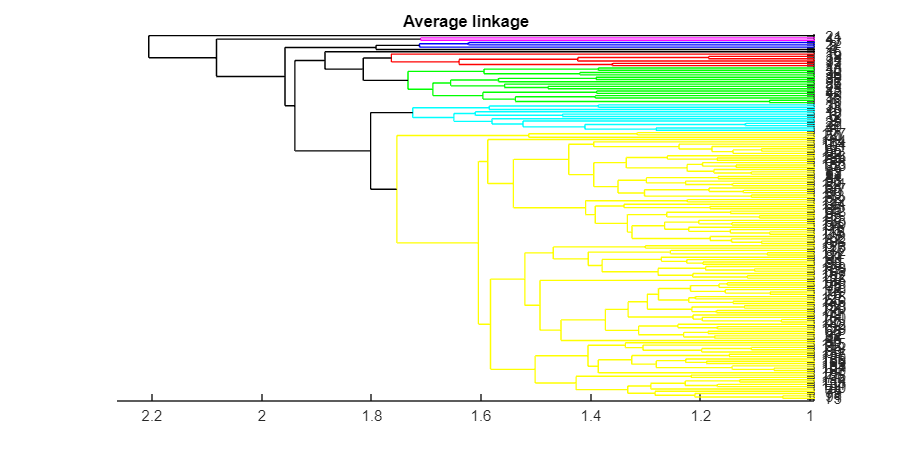

% figure
% subplot(3,1,1)
clf('reset')
figure('Position',[1000,1000,800,400])
dendrogram(Uave, 0, 'Orientation','left', 'colorthreshold', 1.78)
title(['Average linkage'])

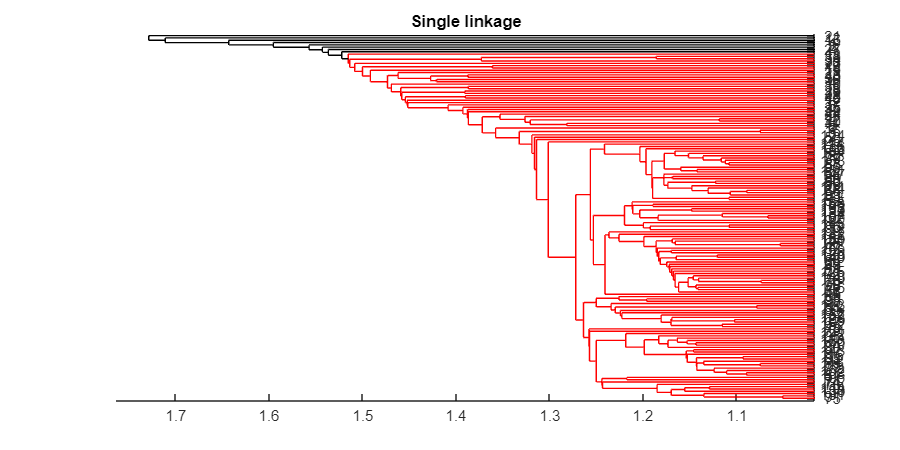

% subplot(3,1,2)
clf('reset')
figure('Position',[1000,1000,800,400])
dendrogram(Umin,0, 'orientation', 'left','ColorThreshold', 1.52)
title('Single linkage')

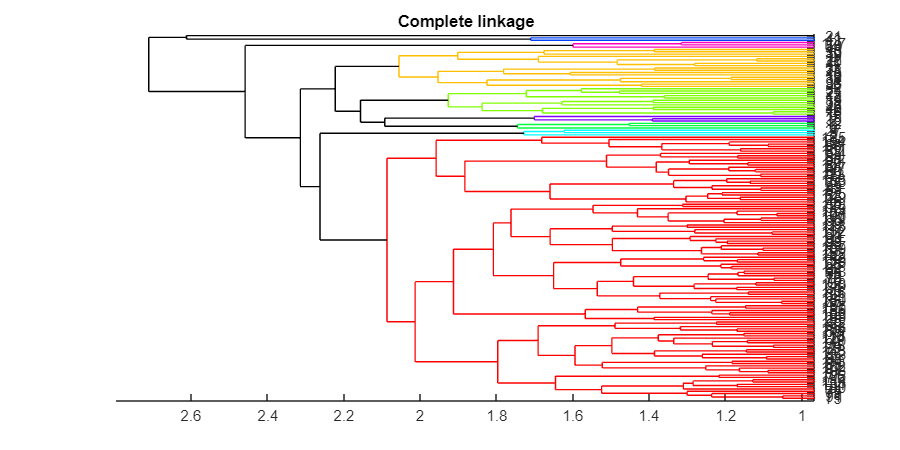

% subplot(3,1,3)
clf('reset')
figure('Position',[1000,1000,800,400])
dendrogram(Umax,0,'orientation', 'left', 'ColorThreshold', 2.09)
title('Complete linkage')

[cophenet(Umin, d) cophenet(Umax, d) cophenet(Uave,d)]

ans =     0.7889    0.7517    0.8360


### 4.2. Non-hierarchical clustering

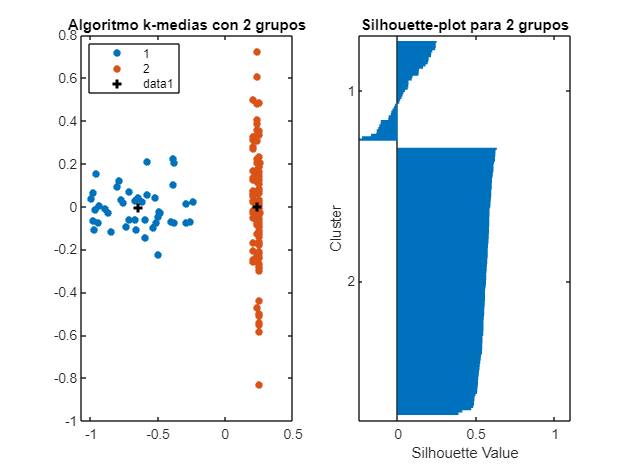

C2 =    -0.6456   -0.0035   -0.0025   -0.0041    0.0005   -0.0064   -0.0222    0.0150    0.0164   -0.0043    0.0028    0.0041   -0.0054    0.0194   -0.0228   -0.0023   -0.0009   -0.0096   -0.0013   -0.0223   -0.0181    0.0048   -0.0007    0.0021    0.0034    0.0087   -0.0026    0.0008   -0.0010    0.0046    0.0025    0.0021   -0.0002    0.0007   -0.0004    0.0001   -0.0004    0.0001   -0.0008   -0.0002
    0.2414    0.0013    0.0009    0.0015   -0.0002    0.0024    0.0083   -0.0056   -0.0061    0.0016   -0.0011   -0.0015    0.0020   -0.0072    0.0085    0.0009    0.0003    0.0036    0.0005    0.0083    0.0067   -0.0018    0.0003   -0.0008   -0.0013   -0.0033    0.0010   -0.0003    0.0004   -0.0017   -0.0009   -0.0008    0.0001   -0.0003    0.0002   -0.0000    0.0001   -0.0000    0.0003    0.0001


s2 = 0.4180

IDX =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


clf('reset')
[C2, s2, IDX] = kmedias2(Y_joint, 9);

## 5. References

Rubin, L., Soundarapandian, P., and Eswaran,P.. (2015). Chronic_Kidney_Disease. UCI Machine Learning Repository. https://doi.org/10.24432/C5G020.

Grané, A. (2023). Multidimensional datasets. Universidad Carlos III de Madrid.

Härdle, W., Simar, L. Applied Multivariate Statistical Analysis. Springer, Second Edition. New York, USA. 2007.